## Formant estimation with LPC Coefficients

Based on: [https://uk.mathworks.com/help/signal/ug/formant-estimation-with-lpc-coefficients.html](https://uk.mathworks.com/help/signal/ug/formant-estimation-with-lpc-coefficients.html)

Example 1: Flute playing note E4 (fundamental frequency of 330 Hz)

clearvars
[flute, Fs] = audioread("test_audio/330 - E3.wav"); % 330 Hz fundamental

% Select a 0.15s segment of signal and apply Hamming window
x = flute(round(Fs*1):round(Fs*1.15));
x1 = x.*hamming(length(x));
sound(x1, Fs);

% Pre-emphasis high-pass filter
% preemph = [1 0.63];
% x1 = filter(1,preemph,x1);

% Plot the spectrum
figure
freq_axis = (0:length(x1)-1)*(Fs/length(x1));
power = abs(fft(x1)).^2/length(x1);
dBpower = 20*log(power);
plot(freq_axis, dBpower)
xlabel("Frequency (Hz)")
ylabel("Power (dB)")
xlim([0, 2500])
grid on
hold on

LPC calculation and formant estimation

n_formants = 6;
lower_bound = 100;   % Lower bound for formant frequencies
bw_bound = 500;      % Maximum bandwidth for each formant
% General rule: model order is 2x expected number of formants (in the frequency range [0, Fs/2]), plus 2.
A = lpc(x1, n_formants*2+2);

formants = lpc_formant_estimation(A, Fs, lower_bound, bw_bound)

formants = 	1.0e+03 *

    0.4124    1.6336    3.9887


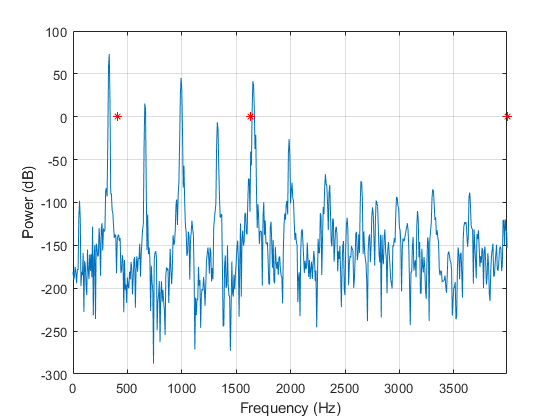


% Display formant locations on spectrum
plot(formants, zeros([length(formants)]), "r*")
xlim([0, formants(end)])
hold off

Repeat across all flute notes to observe constancy of formants

note_formants = [];
myDir = "test_audio"; %gets directory
myFiles = dir(fullfile(myDir,'*.wav')); %gets all wav files in struct
for k = 1:length(myFiles)
    baseFileName = myFiles(k).name;
    fullFileName = fullfile(myDir, baseFileName);
    
    [flute, Fs] = audioread(fullFileName); 
    sep_name = split(baseFileName);
    f0 = str2double(sep_name(1)); % Get fundamental frequency from filename
    
    % Select a 0.15s segment of signal and apply Hamming window
    x = flute(round(Fs*1):round(Fs*1.15));
    x1 = x.*hamming(length(x));
    %sound(x1, Fs);
    
    A = lpc(x1, n_formants*2+2);
    formants = lpc_formant_estimation(A, Fs, lower_bound, bw_bound);
    if(length(formants) < 3)
        formants = horzcat(formants, NaN(1, 3-length(formants)));
    end
    note_formants = vertcat(note_formants, horzcat(f0, formants));
end
note_formants = circshift(note_formants, [-6, 0]) % Format: f0, f1, f2, f3, etc.

note_formants = 	1.0e+03 *

    0.1960    0.5337    1.5224       NaN
    0.2080    0.5017    1.5838       NaN
    0.2200    1.3409       NaN       NaN
    0.2330    0.3199    1.3321       NaN
    0.2470    0.3857    1.4510       NaN
    0.2620    0.7753    1.6401    4.0580
    0.2770    0.8649    1.7481    3.9732
    0.2940    0.5392    1.7822    4.1265
    0.3110    0.2237    1.4881    4.0405
    0.3300    0.4124    1.6336    3.9887


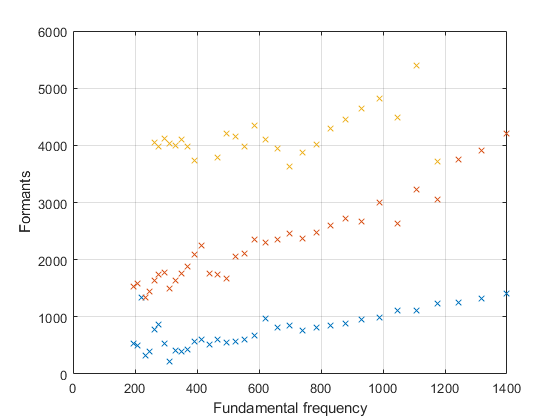

fundamental = note_formants(:,1);
f1 = note_formants(:, 2);
f2 = note_formants(:, 3);
f3 = note_formants(:, 4);

% Plot formant frequencies against fundamental
plot(note_formants(:, 1), note_formants(:, 2:4), "x")
grid on
xlabel("Fundamental frequency")
ylabel("Formants")

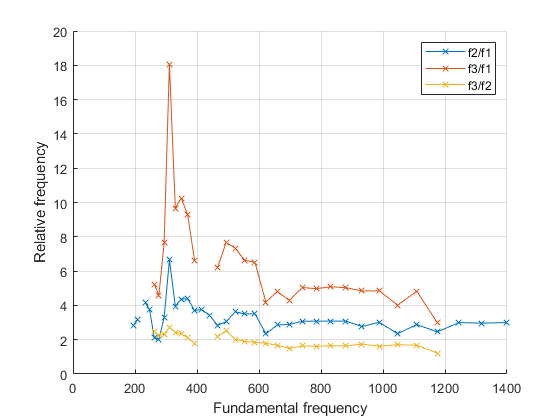


figure
hold on
plot(fundamental, f2./f1, "-x", "DisplayName", "f2/f1")
plot(fundamental, f3./f1, "-x", "DisplayName", "f3/f1")
plot(fundamental, f3./f2, "-x", "DisplayName", "f3/f2")
legend
grid on
xlabel("Fundamental frequency")
ylabel("Relative frequency")
hold off

## Recreating with VOICEBOX

[http://www.ee.ic.ac.uk/hp/staff/dmb/voicebox/voicebox.html#lpc](http://www.ee.ic.ac.uk/hp/staff/dmb/voicebox/voicebox.html#lpc)

[Voicebox LPC utilities help](file:///C:/Users/Tom/Dropbox/Work/Electronic%20and%20Information%20Eng%20-%204th%20Year/MEng%20Project/Scripts/voicebox/doc/lpc.html)

Break the signal into frames using enframe

[flute, Fs] = audioread("test_audio/330 - E3.wav"); % 330 Hz fundamental

frame_len = 0.150; % Frame length in s
x = v_enframe(flute, hamming(frame_len*Fs), frame_len*Fs);  % Format: (frames, samples_in_frame)

Calculate coefficients for each frame using one of the dedicated LPC Analysis functions:

 [lpcauto](mdoc/v_mfiles/v_lpcauto.html) for autocorrelation analysis and [lpccovar](mdoc/v_mfiles/v_lpccovar.html) for covariance analysis.

The analysis order, *p*, denotes the number of poles in the resultant autoregressive filter.

For speech processing p is at least 2 * Fs * l/c where l is the vocal tract length (typically 0.17 m) and c=343 m/s giving p = f/1000.

Returns the AR coefficients and the residual *e*.

num_formants = 6;
%[ar,e]=v_lpcauto(x, num_formants*2+2, [], 'r', 'e');
[ar,e]=v_lpcauto(flute, num_formants*2+2, [frame_len*Fs, frame_len*Fs, 0], 's', 'e'); % "s"= Hamming window

The [v_lpcar2ff](http://www.ee.ic.ac.uk/hp/staff/dmb/voicebox/mdoc/v_mfiles/v_lpcar2ff.html) function converts AR coefficients to the complex spectrum.

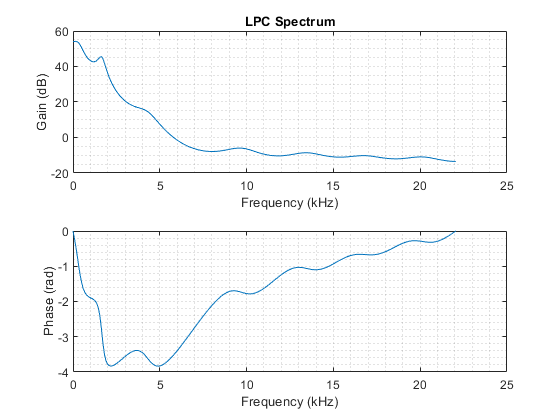

[ff,f] = v_lpcar2ff(ar, 256); % f is normalised frequencies from 0 to 0.5 * Fs, ff is the spectrum
ff = ff(7, :);
% Plot spectrum
subplot(2,1,1);
plot(f*Fs/1000,db(abs(ff)));
xlabel('Frequency (kHz)');
ylabel('Gain (dB)');
grid minor
title('LPC Spectrum');
subplot(2,1,2);
plot(f*Fs/1000,unwrap(angle(ff)));
xlabel('Frequency (kHz)');
ylabel('Phase (rad)');
grid minor

Calculate roots of AR coefficients and convert to formant frequencies and bandwidths.

[v_lpcar2zz(ar)](file:///C:/Users/Tom/Dropbox/Work/Electronic%20and%20Information%20Eng%20-%204th%20Year/MEng%20Project/Scripts/voicebox/doc/mdoc/v_mfiles/v_lpcar2zz.html) finds the z-plane roots, but is just a frame-looped version of the matlab function roots(ar).

[v_lpczz2ss](file:///C:/Users/Tom/Dropbox/Work/Electronic%20and%20Information%20Eng%20-%204th%20Year/MEng%20Project/Scripts/voicebox/doc/mdoc/v_mfiles/v_lpczz2ss.html) converts z-plane poles to s-plane poles in normalised Hz. Multiplying ss * Fs, a formant at frequency f and bandwidth b gives an s-plane pole pair of approximately $-\frac{b}{2}\pm \mathrm{jf}$

lower_bound = 100;   % Lower bound for formant frequencies
bw_bound = 500;      % Maximum bandwidth for each formant
formants = lpc_formant_estimation(ar(7, :), Fs, lower_bound, bw_bound)

formants = 	1.0e+03 *

    0.3066    1.6668    4.2997



zz = v_lpcar2zz(ar); % From AR coefficients to z-plane poles
ss = v_lpczz2ss(zz); % From z-plane to s-plane poles
% Remove negative complex conjugates, since roots come in conjugate pairs
ss = reshape(ss(imag(ss) > 0), [], 7);
frequencies = imag(ss*Fs);
bandwidths = -2*real(ss*Fs);

form = frequencies(7, :);
band = bandwidths(7, :);

ss_formants = form(and(band < 1000, form > 100))

ss_formants = 	1.0e+03 *

    1.6668    0.3680


ss_bandwidths = band(and(band < 1000, form > 100))

ss_bandwidths =   367.7339  482.8937
